eng = eng_tot;
[error,indx] = max(abs(1-eng));
ff1 = ff{1,1};

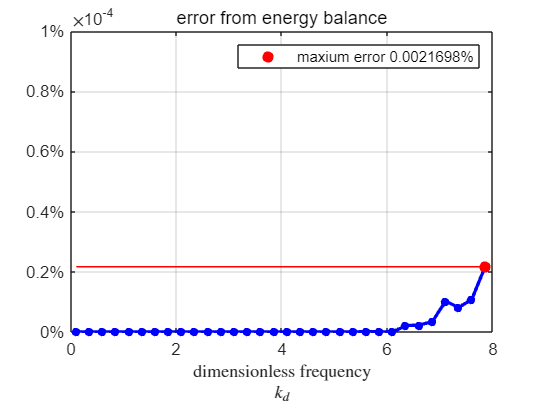

错误使用 open
输入参数的数目不足。

p1 = plot(ff1,abs(1-eng), ...
	'LineWidth',2, 'Color','b',...
	'Marker','o',MarkerSize=5,MarkerFaceColor='b',...
	MarkerEdgeColor='none');
hold on
p2 = plot(ff1(indx),error,'r.',MarkerSize=20);
p3 = plot(ff1,error*ones(size(ff1)),'r');
hold off
xlabel(["dimensionless frequency"; "$$k_d$$"],Interpreter="latex");
ytickformat('percentage')
grid on


ylim([0,1e-4])
legendTxt = ['maxium error ', num2str(error*100),'%'];
legend("",legendTxt)
title('error from energy balance')